# Task 3: Incremental Fault Diagnosis  

Condition monitoring includes discriminating between faulty and healthy states (*fault detection*) or, when a fault state is present, determining the source of the fault (*fault diagnosis*). To design an algorithm for condition monitoring, you use condition indicators extracted from system data to train a decision model that can analyze indicators extracted from test data to determine the current system state. 

## 1. Prepare the data for classifying faults

In this exercise, we will train a Naive Bayes model in a incremental manner for fault diagnosis of bearings. We treat the inner race fault, outer race fault and normal as three individual classes and build model to classify them. 

To frame up the problem, we will split the original training dataset into two datasets. Dataset 1 only consists normal and inner race fault with 60 samples. Dataset 2 is the rest of the training dataset with all three classes.

load features.mat
feaTrain1 = feaTrain([1:30,331:360],:)

feaTrain1 = 60×7 table
        label         data_ps_spec/PeakAmp3    data_ps_spec/PeakAmp4    data_ps_spec/PeakAmp5    data_ps_spec/PeakAmp6    data_ps_spec/PeakAmp7    data_ps_spec/BandPower
    ______________    _____________________    _____________________    _____________________    _____________________    _____________________    ______________________

    InnerRaceFault         0.00083332               0.00081439               0.00080294               0.00072909               0.00071383                    4.27        
    InnerRaceFault          0.0012205                0.0011876                0.0010295               0.00098555               0.00095191                  3.6811        
    InnerRaceFault         0.00098629               0.0008

feaTrain([1:30,331:360,201:230],:)=[];
feaTrain2 = feaTrain(randperm(height(feaTrain)),:);
rng(0,"twister"); 
feaTrain1 = feaTrain1(randperm(height(feaTrain1)),:);
feaTrain2 = feaTrain2(randperm(height(feaTrain2)),:);



## **2. Train Initial** Model

Fit a Naive Bayes classification model with dataset 1 where only normal and inner race fault are represented.

IncrementalMdl = incrementalClassificationECOC("MaxNumClasses",3,"MetricsWarmupPeriod",20)

IncrementalMdl =   incrementalClassificationECOC

            IsWarm: 0
           Metrics: [1×2 table]
        ClassNames: [1×0 double]
    ScoreTransform: 'none'
    BinaryLearners: {3×1 cell}
        CodingName: 'onevsone'
          Decoding: 'lossweighted'


  Properties, Methods


IncrementalMdl = fit(IncrementalMdl,feaTrain1{:,2:end},feaTrain1{:,1});

Let's evaluate the initial model using the entire testing dataset. As you can see, the model accurately classifies normal and inner race faults, but struggles with outer race faults. This result is expected, since the model was not trained on examples of the outer race fault class and, therefore, can only distinguish between normal and inner race faults.

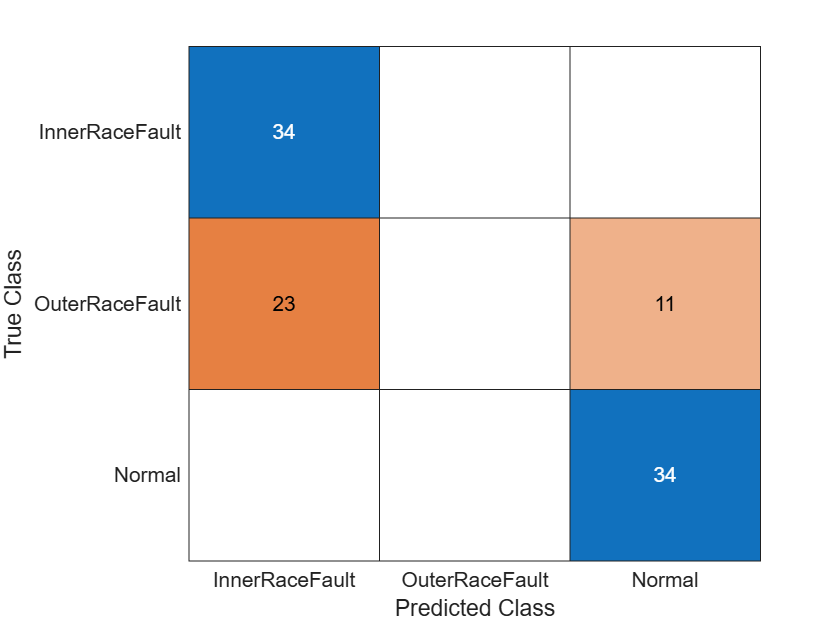

YPred1 = predict(IncrementalMdl,feaTest{:,2:end});
figure
ConfusionMatTest1 = confusionchart(feaTest{:,1},YPred1);

## **3. Incrementally Update** Model

As additional data (Dataset 2) becomes available, update the initial Naive Bayes model with these new observations. Monitor how the model parameter μ₁₂ and the classification accuracy on the testing dataset change over time.

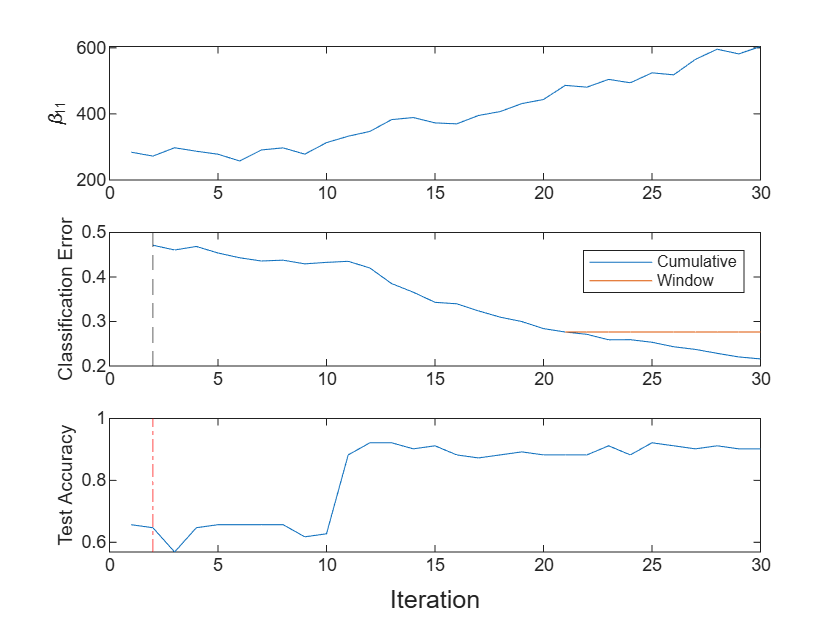

% Incremental fitting
rng(0,"twister");

nil = height(feaTrain2);
numObsPerChunk = 10;
nchunk = floor(nil/numObsPerChunk);
mc = array2table(zeros(nchunk,2),VariableNames=["Cumulative","Window"]);
beta11 = zeros(nchunk+1,1);  
testaccuracy = zeros(nchunk,1);
% Incremental fitting
for j = 1:nchunk
    ibegin = min(nil,numObsPerChunk*(j-1) + 1);
    iend   = min(nil,numObsPerChunk*j);
    idx = ibegin:iend;    
    IncrementalMdl = updateMetricsAndFit(IncrementalMdl,feaTrain2{idx,2:end},feaTrain2{idx,1});
    mc{j,:} = IncrementalMdl.Metrics{"ClassificationError",:};
    beta11(j) = IncrementalMdl.BinaryLearners{1}.Beta(1);
    YPred2Temp = predict(IncrementalMdl,feaTest{:,2:end});
    testaccuracy(j)= sum(YPred2Temp==feaTest{:,1})/height(feaTest);
end

% Plot the performance metrics and μ12 evolve during training, plot them on separate tiles.
t = tiledlayout(3,1);
nexttile
plot(beta11)
ylabel("\beta_{11}")
xlim([0 nchunk])
nexttile
plot(mc.Variables)
xlim([0 nchunk])
ylabel("Classification Error")
xline(IncrementalMdl.MetricsWarmupPeriod/numObsPerChunk,"--")
legend(mc.Properties.VariableNames)
xlabel(t,"Iteration")
nexttile
h = plot(testaccuracy);
xlim([0 nchunk]);
ylabel('Test Accuracy')
xline(IncrementalMdl.MetricsWarmupPeriod/numObsPerChunk,'r-.');
xlabel(t,'Iteration')

## **4. Diagnose Fault Type for New Data**

Evaluate the model performance with the entire testing dataset.  

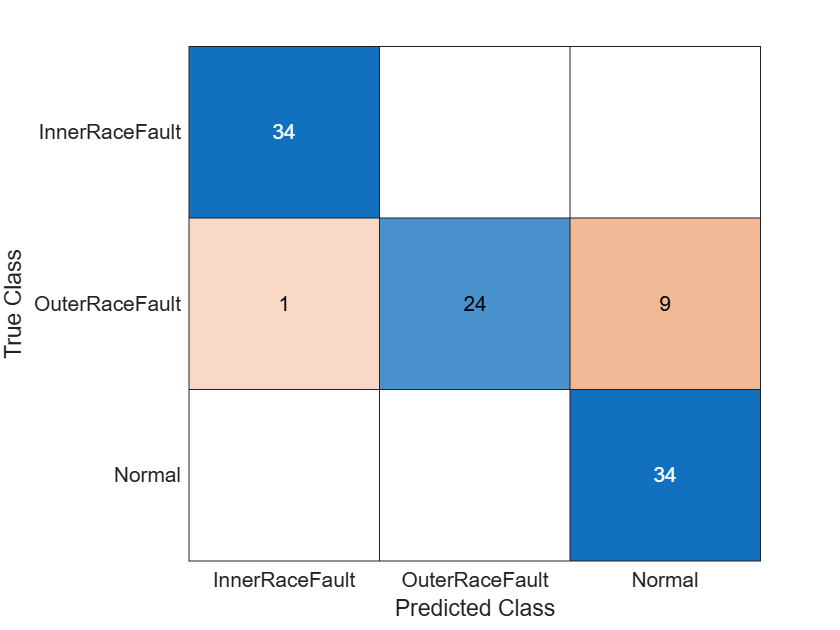

figure
YPred2 = predict(IncrementalMdl,feaTest{:,2:end});
ConfusionMatTest2 = confusionchart(feaTest{:,1},YPred2);